clear;
clc;
FS = 48000;

# **CA1-Q4-810101429**

#### ***Reading the input & filtering it:***

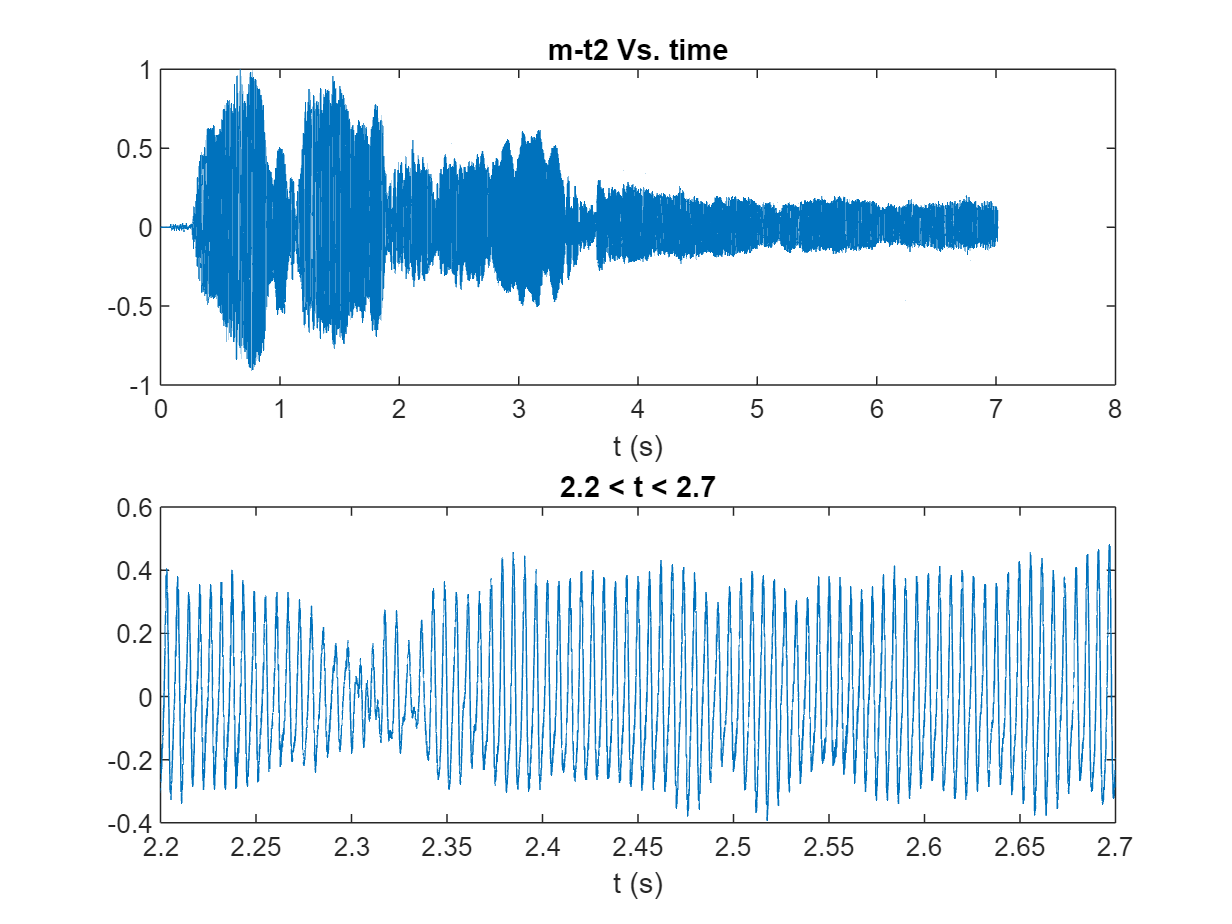

x_in = audioread('m_t2.mp3');
x_in = x_in/max(abs(x_in));

% sound(x_in, FS);

time_domain = (0:length(x_in)-1) / FS;
time_domain2 = time_domain';
figure;
subplot(2,1,1);
plot(time_domain, x_in);
xlabel('t (s)');
title('m-t2 Vs. time');
subplot(2,1,2);
plot(time_domain, x_in);
xlabel('t (s)');
title('2.2 < t < 2.7');
xlim([2.2, 2.7]);

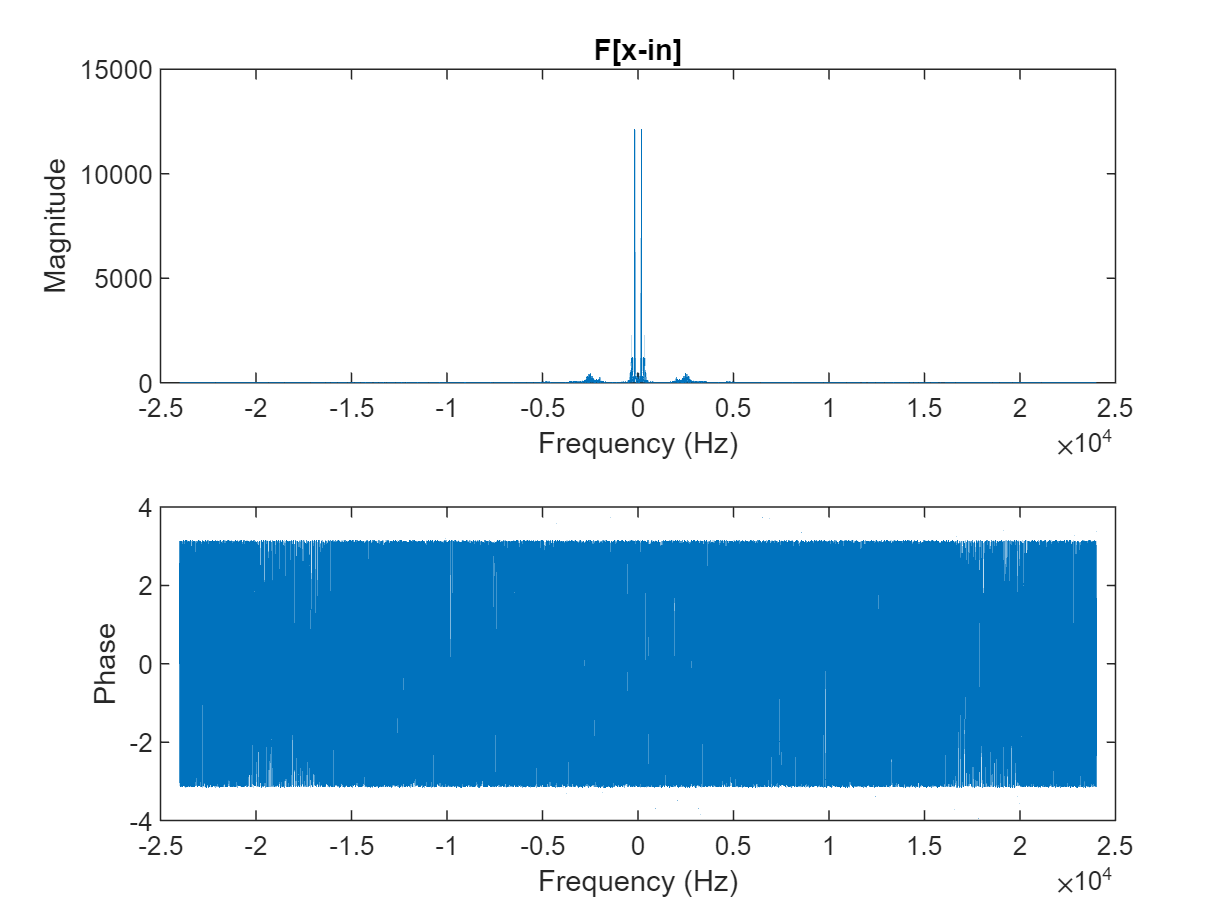

F_x = fftshift(fft(x_in));
n_x = length(x_in);
f_x = (-n_x/2:n_x/2-1)*(FS/n_x);


figure;
subplot(2,1,1);
plot(f_x,abs(F_x));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x-in]');
subplot(2,1,2);
plot(f_x,angle(F_x));
xlabel('Frequency (Hz)');
ylabel('Phase');

Fx_filtered_5k = LPfilter(F_x, f_x, 5000);
x_in_filtered_5k = ifft(ifftshift(Fx_filtered_5k));

***FM & NBFM modulation:***

Ts = 1/FS;

- **f_delta = 0.1:**

x_c_FM_01 = FM( x_in_filtered_5k, time_domain2, 0.1, Ts);
x_c_NBFM_01 = NBFM( x_in_filtered_5k, time_domain2, 0.1, Ts);
F_x_c_FM_01 = fftshift(fft(x_c_FM_01));
F_x_c_NBFM_01 = fftshift(fft(x_c_NBFM_01));

mse_NBFM_01 = immse(x_c_NBFM_01 , x_c_FM_01);

fprintf('\n f-delta = 0.1:\n  mse for NBFM : %e\n', mse_NBFM_01);


 f-delta = 0.1:
  mse for NBFM : 1.912816e-16


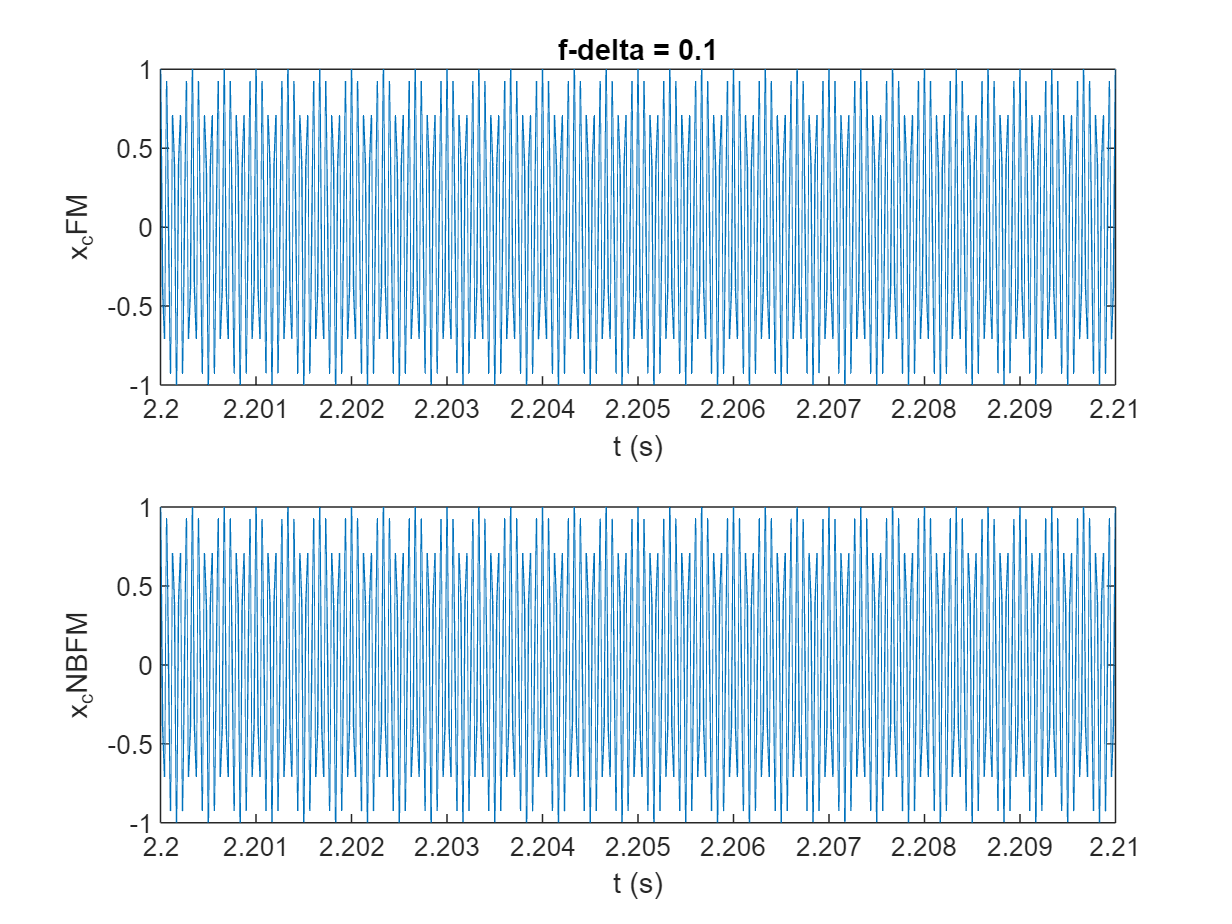

figure;
subplot(2,1,1);
plot(time_domain, x_c_FM_01);
xlabel('t (s)');
ylabel('x_cFM');
title('f-delta = 0.1');
xlim([2.2, 2.21]);
subplot(2,1,2);
plot(time_domain, x_c_NBFM_01);
xlabel('t (s)');
ylabel('x_cNBFM');
xlim([2.2, 2.21]);

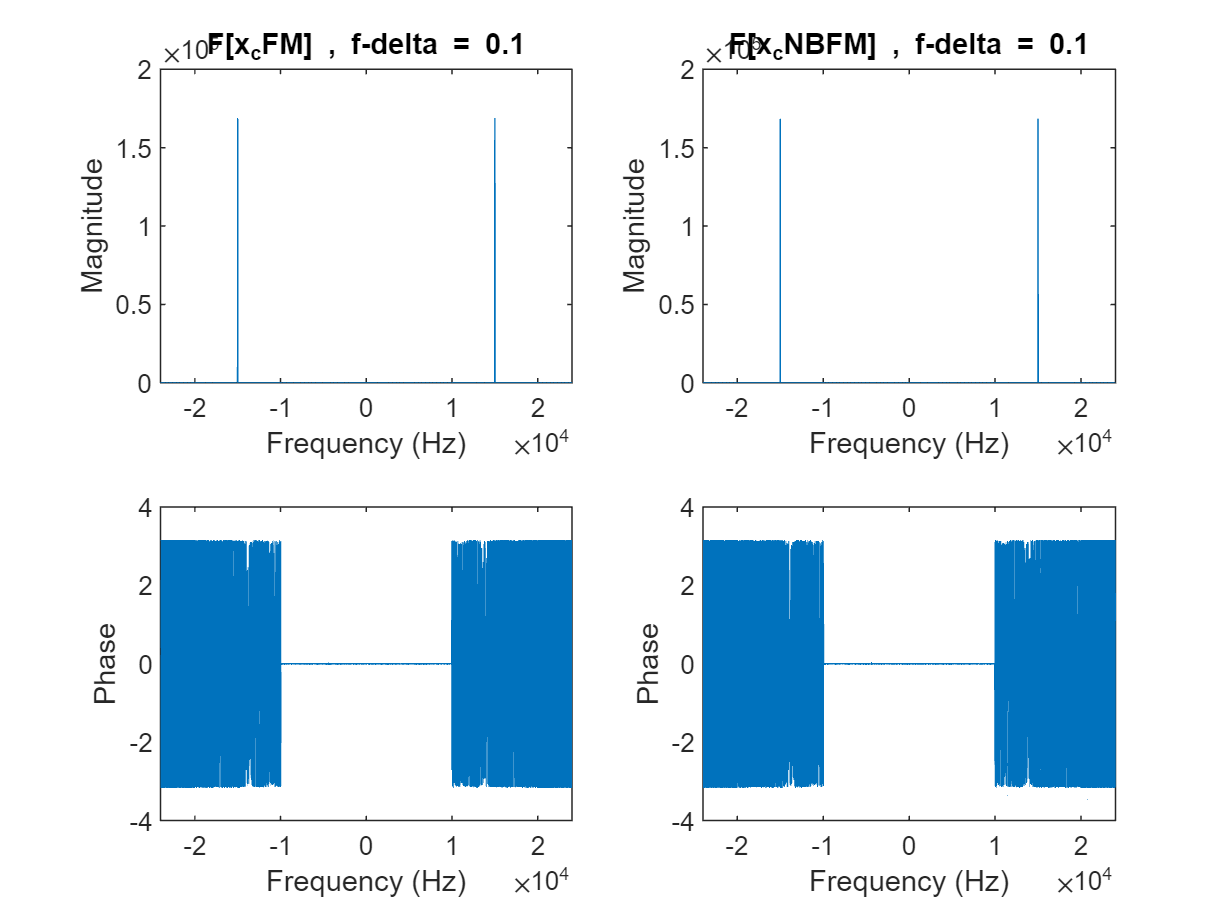

figure;
subplot(2,2,1);
plot(f_x,abs(F_x_c_FM_01));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_cFM] , f-delta = 0.1');
subplot(2,2,3);
plot(f_x,angle(F_x_c_FM_01));
xlabel('Frequency (Hz)');
ylabel('Phase');
subplot(2,2,2);
plot(f_x,abs(F_x_c_NBFM_01));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_cNBFM] , f-delta = 0.1');
subplot(2,2,4);
plot(f_x,angle(F_x_c_NBFM_01));
xlabel('Frequency (Hz)');
ylabel('Phase');

- **f_delta = 2000:**

x_c_FM_2k = FM( x_in_filtered_5k, time_domain2, 2000, Ts);
x_c_NBFM_2k = NBFM( x_in_filtered_5k, time_domain2, 2000, Ts);
F_x_c_FM_2k = fftshift(fft(x_c_FM_2k));
F_x_c_NBFM_2k = fftshift(fft(x_c_NBFM_2k));

mse_NBFM_2k = immse(x_c_NBFM_2k , x_c_FM_2k);

fprintf('\n f-delta = 2k:\n  mse for NBFM : %f\n', mse_NBFM_2k);


 f-delta = 2k:
  mse for NBFM : 4.941559


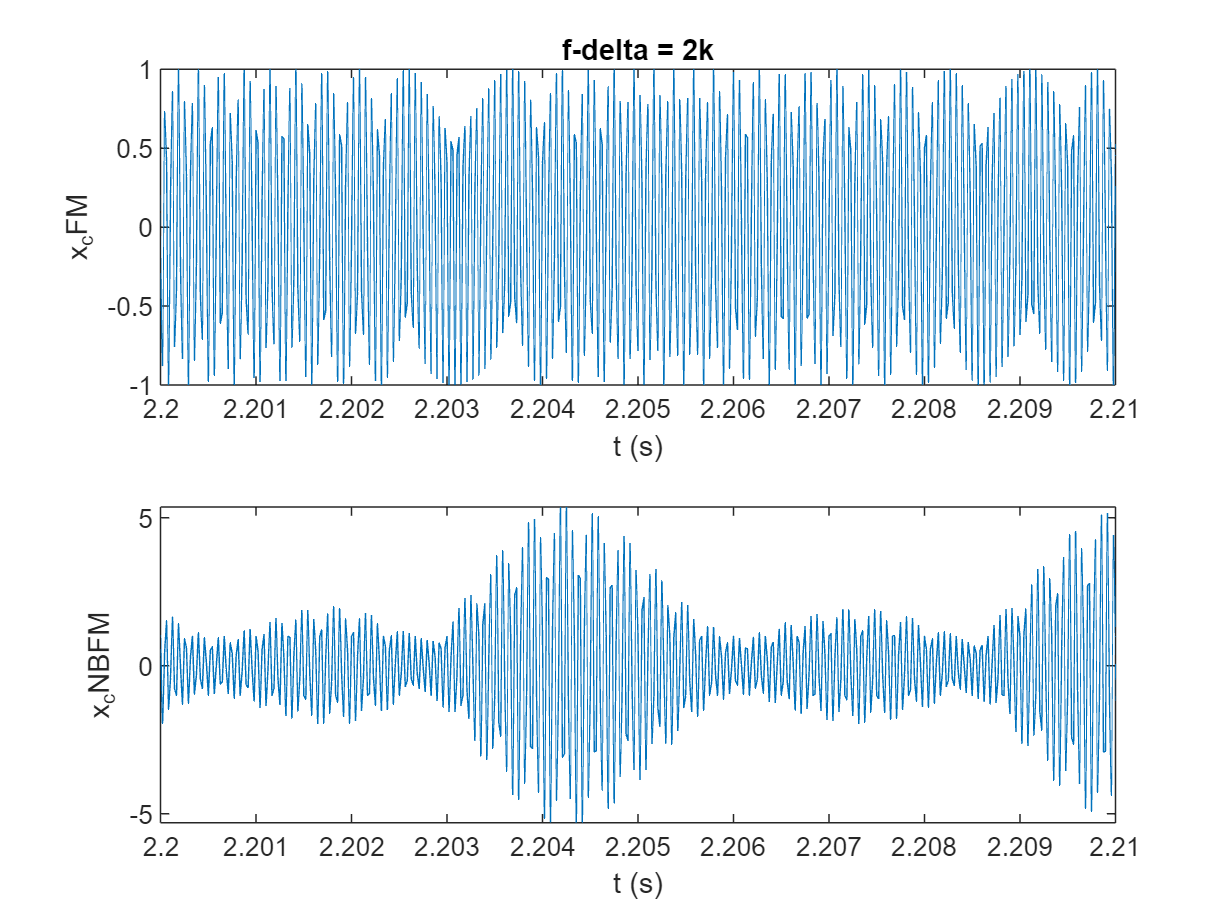

figure;
subplot(2,1,1);
plot(time_domain, x_c_FM_2k);
xlabel('t (s)');
ylabel('x_cFM');
title('f-delta = 2k');
xlim([2.2, 2.21]);
subplot(2,1,2);
plot(time_domain, x_c_NBFM_2k);
xlabel('t (s)');
ylabel('x_cNBFM');
xlim([2.2, 2.21]);

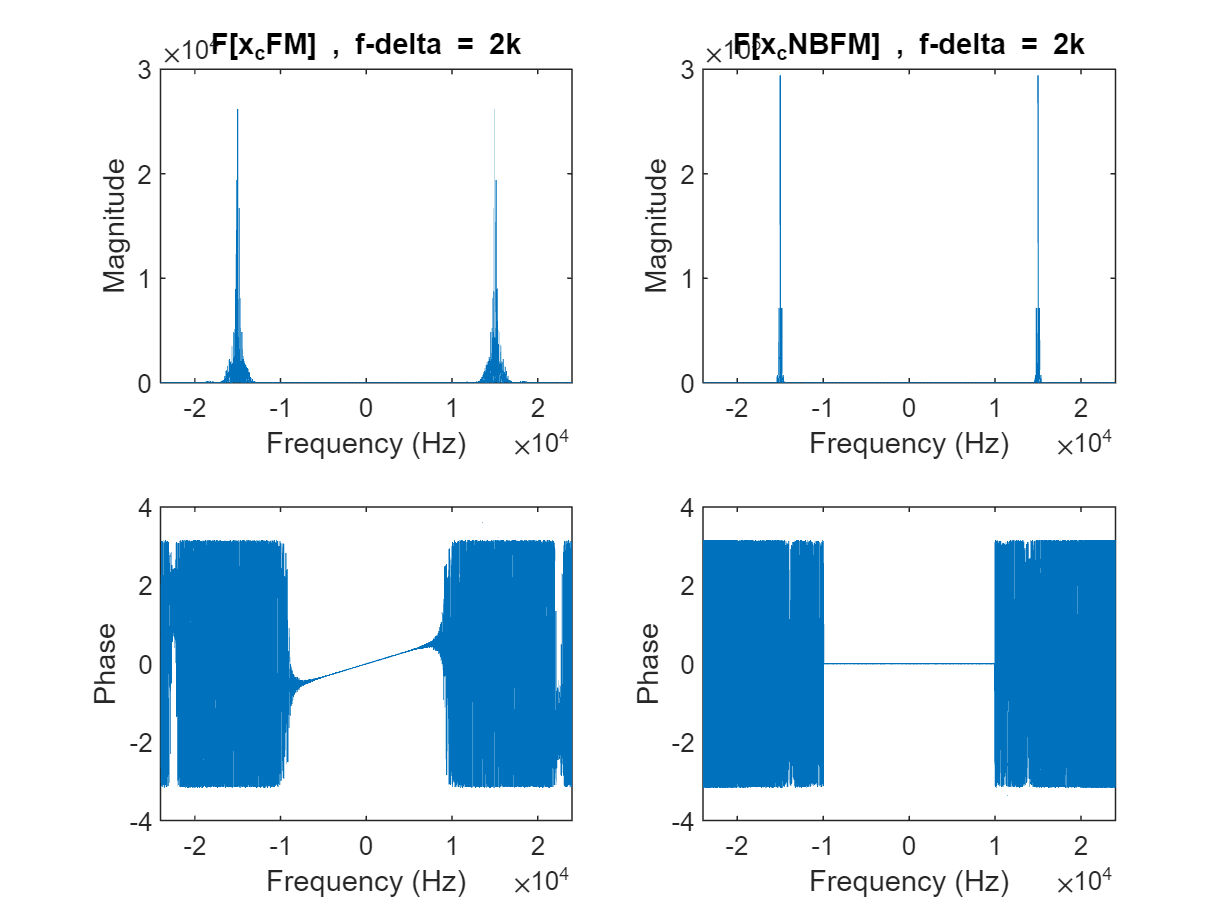

figure;
subplot(2,2,1);
plot(f_x,abs(F_x_c_FM_2k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_cFM] , f-delta = 2k');
subplot(2,2,3);
plot(f_x,angle(F_x_c_FM_2k));
xlabel('Frequency (Hz)');
ylabel('Phase');
subplot(2,2,2);
plot(f_x,abs(F_x_c_NBFM_2k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_cNBFM] , f-delta = 2k');
subplot(2,2,4);
plot(f_x,angle(F_x_c_NBFM_2k));
xlabel('Frequency (Hz)');
ylabel('Phase');

- **f_delta = 5000:**

x_c_FM_5k = FM( x_in_filtered_5k, time_domain2, 5000, Ts);
x_c_NBFM_5k = NBFM( x_in_filtered_5k, time_domain2, 5000, Ts);
F_x_c_FM_5k = fftshift(fft(x_c_FM_5k));
F_x_c_NBFM_5k = fftshift(fft(x_c_NBFM_5k));

mse_NBFM_5k = immse(x_c_NBFM_5k , x_c_FM_5k);

fprintf('\n f-delta = 5k:\n  mse for NBFM : %f\n', mse_NBFM_5k);


 f-delta = 5k:
  mse for NBFM : 27.286130


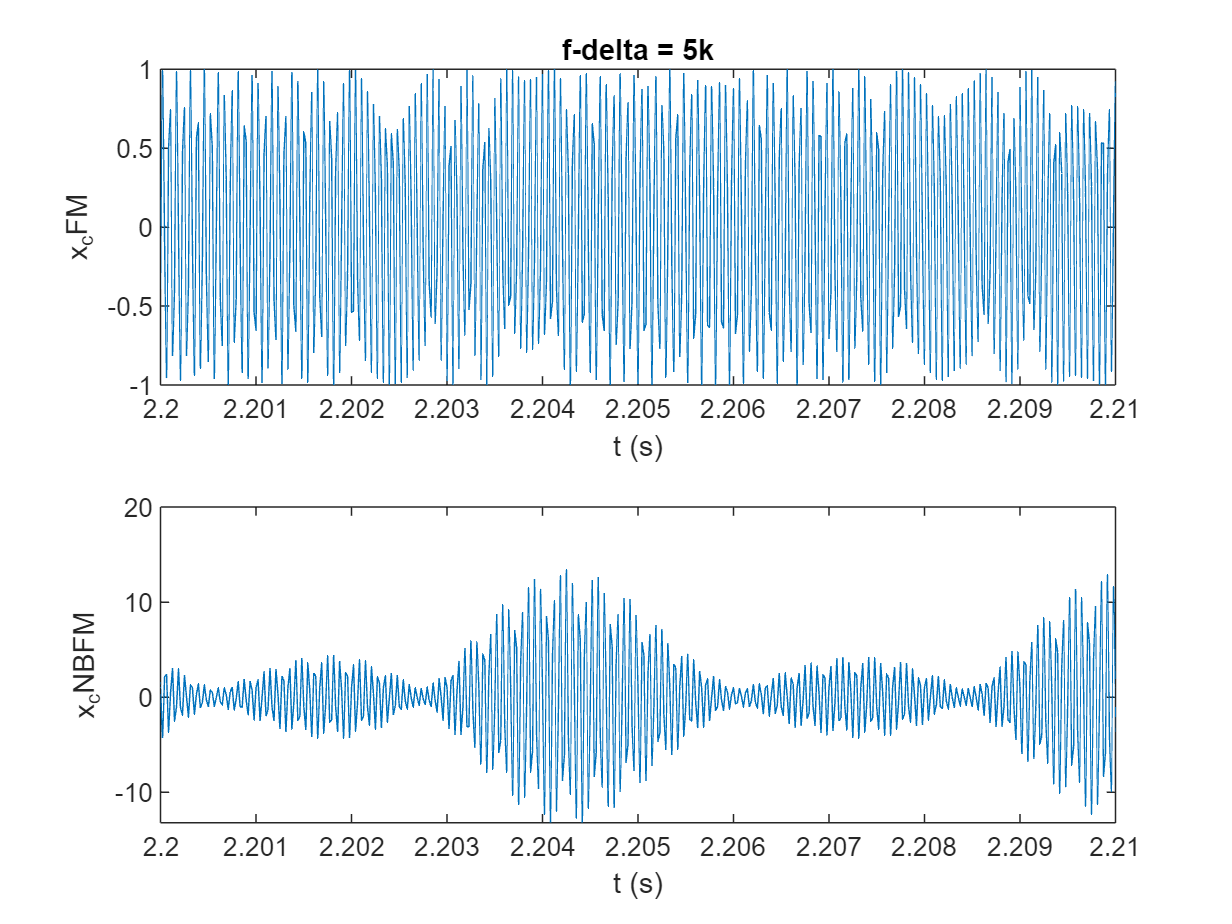


figure;
subplot(2,1,1);
plot(time_domain, x_c_FM_5k);
xlabel('t (s)');
ylabel('x_cFM');
title('f-delta = 5k');
xlim([2.2, 2.21]);
subplot(2,1,2);
plot(time_domain, x_c_NBFM_5k);
xlabel('t (s)');
ylabel('x_cNBFM');
xlim([2.2, 2.21]);

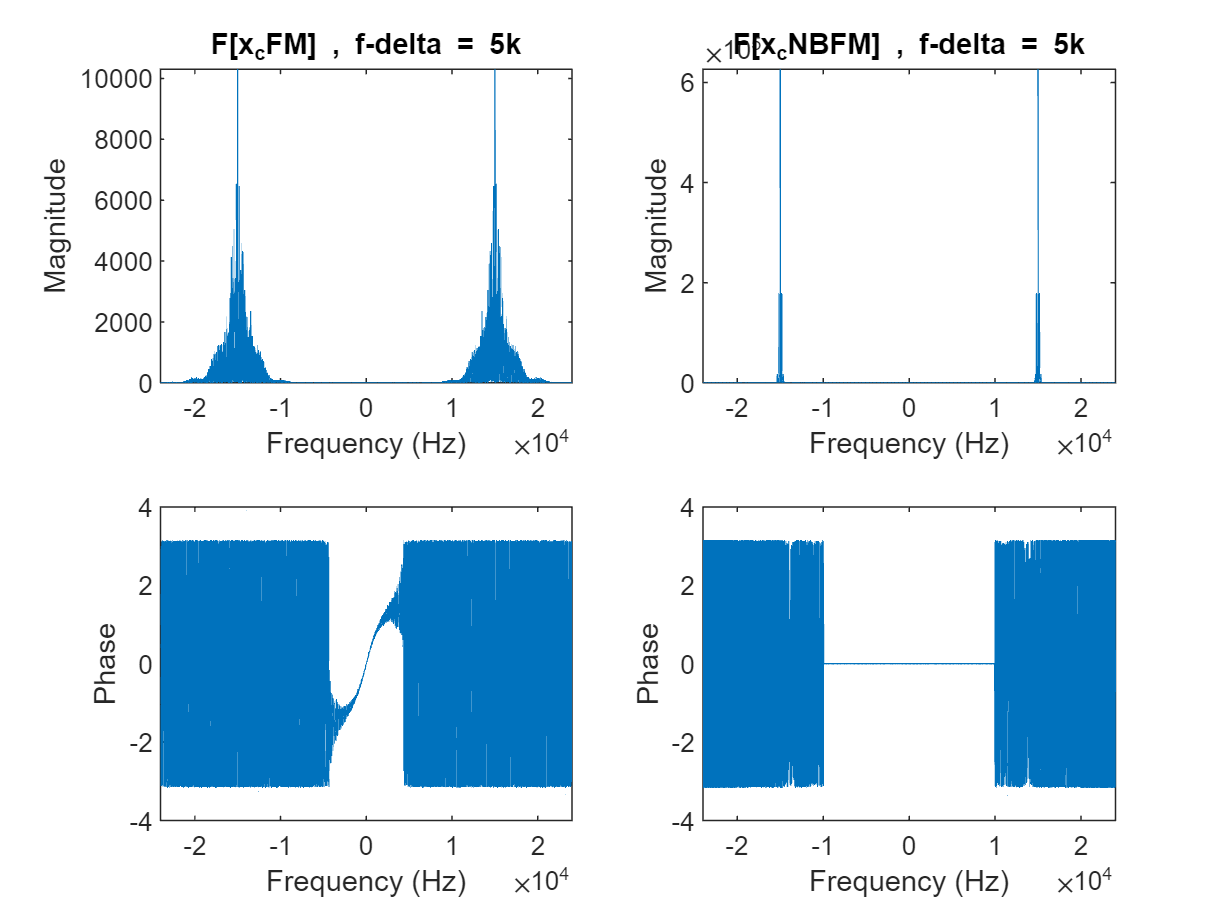

figure;
subplot(2,2,1);
plot(f_x,abs(F_x_c_FM_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_cFM] , f-delta = 5k');
subplot(2,2,3);
plot(f_x,angle(F_x_c_FM_5k));
xlabel('Frequency (Hz)');
ylabel('Phase');
subplot(2,2,2);
plot(f_x,abs(F_x_c_NBFM_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_cNBFM] , f-delta = 5k');
subplot(2,2,4);
plot(f_x,angle(F_x_c_NBFM_5k));
xlabel('Frequency (Hz)');
ylabel('Phase');

- **f_delta = 10000:**

x_c_FM_10k = FM( x_in_filtered_5k, time_domain2, 10000, Ts);
x_c_NBFM_10k = NBFM( x_in_filtered_5k, time_domain2, 10000, Ts);
F_x_c_FM_10k = fftshift(fft(x_c_FM_10k));
F_x_c_NBFM_10k = fftshift(fft(x_c_NBFM_10k));

mse_NBFM_10k = immse(x_c_NBFM_10k , x_c_FM_10k);

fprintf('\n f-delta = 10k:\n  mse for NBFM : %f\n', mse_NBFM_10k);


 f-delta = 10k:
  mse for NBFM : 107.683651


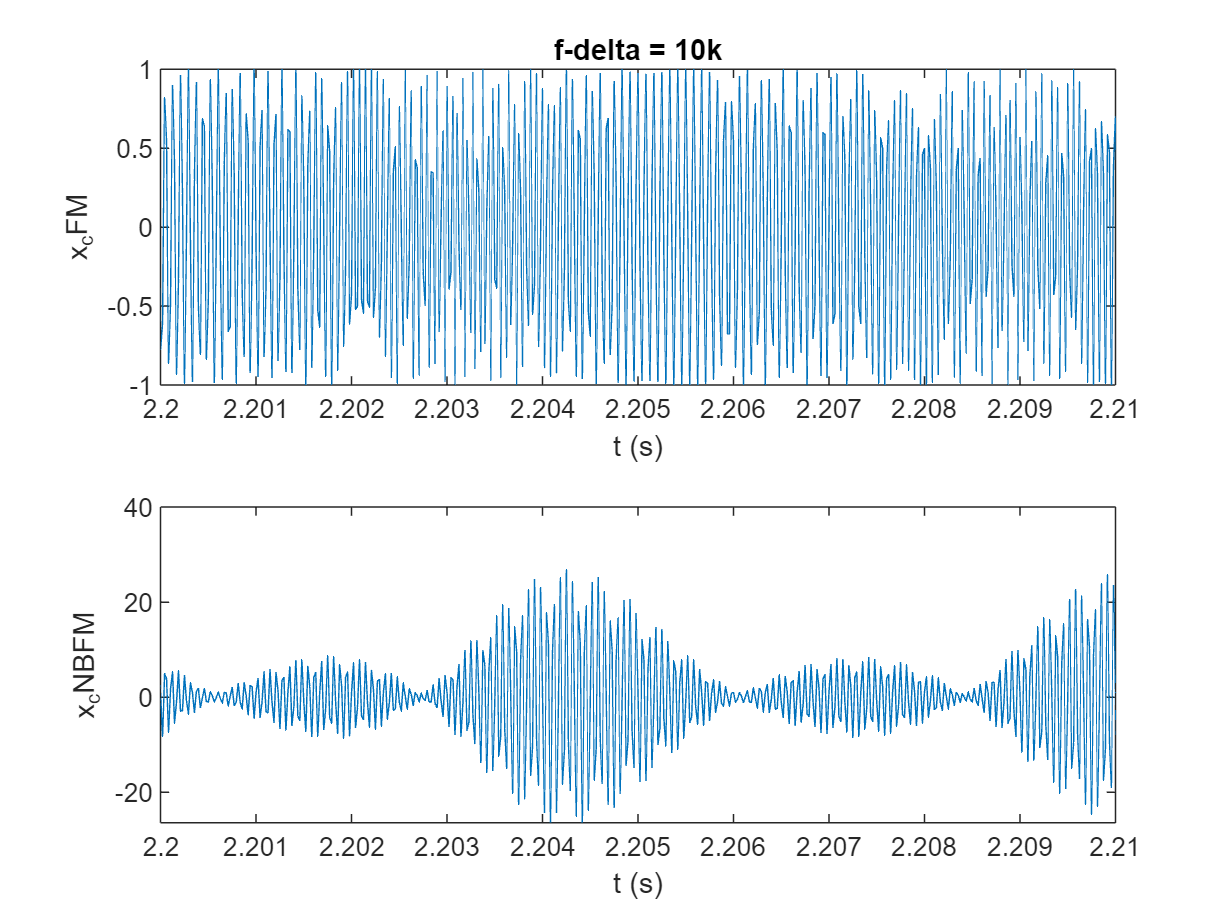

figure;
subplot(2,1,1);
plot(time_domain, x_c_FM_10k);
xlabel('t (s)');
ylabel('x_cFM');
title('f-delta = 10k');
xlim([2.2, 2.21]);
subplot(2,1,2);
plot(time_domain, x_c_NBFM_10k);
xlabel('t (s)');
ylabel('x_cNBFM');
xlim([2.2, 2.21]);

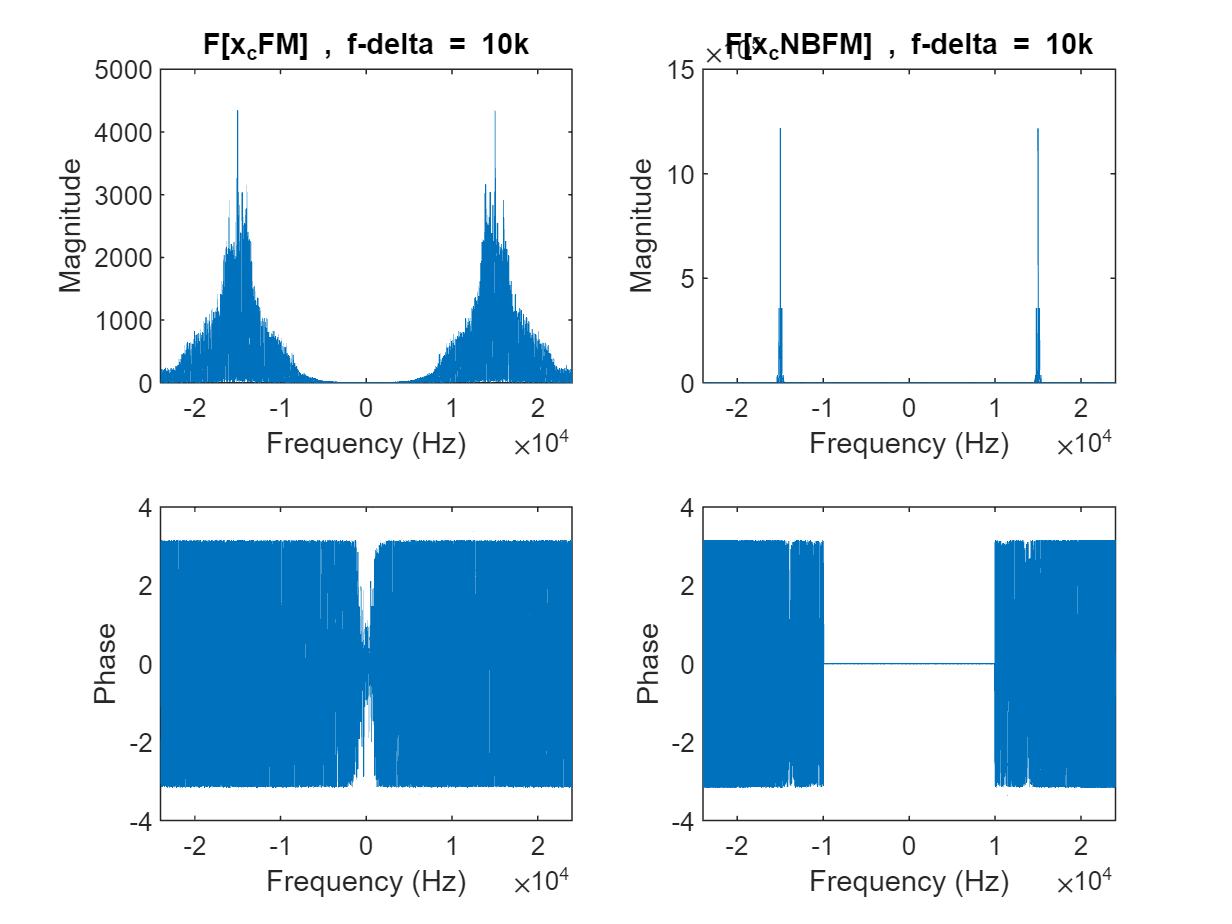


figure;
subplot(2,2,1);
plot(f_x,abs(F_x_c_FM_10k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_cFM] , f-delta = 10k');
subplot(2,2,3);
plot(f_x,angle(F_x_c_FM_10k));
xlabel('Frequency (Hz)');
ylabel('Phase');
subplot(2,2,2);
plot(f_x,abs(F_x_c_NBFM_10k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_cNBFM] , f-delta = 10k');
subplot(2,2,4);
plot(f_x,angle(F_x_c_NBFM_10k));
xlabel('Frequency (Hz)');
ylabel('Phase');

***FM modulating function:***

function FM_modulated = FM (input_signal, time_domain, f_delta, ts)
    fc = 15000; %% modulating frequency
    integrated_input = cumsum(input_signal)*ts;
    FM_modulated = cos(2*pi*fc*time_domain + 2*pi*f_delta*integrated_input);
end

***NBFM modulating function:***

function NBFM_modulated = NBFM (input_signal, time_domain, f_delta, ts)
    fc = 15000; %% modulating frequency
    integrated_input = cumsum(input_signal)*ts;
    NBFM_modulated = cos(2*pi*fc*time_domain) - ( sin(2*pi*fc*time_domain).* (2*pi*f_delta*integrated_input));
end

***Low-Pass filter:***

function New_F = LPfilter(pre_F,freq_vector, f)
    n = length(freq_vector);
    New_F=zeros(n,1);
    for i = (1:n)
        if(abs(freq_vector(i)) < f)
            New_F(i)=pre_F(i); 
        end
    end
end